### 初始化

clc;
clear

### 参数设置

M = 70000;
Fs = 10E6;
% pathname = 'Data\Instrument_Capture_2023_761k_2.csv';
pathname = 'FilterAfter.csv';

### 数据读取

wave_data = readmatrix(pathname);
vout = wave_data(1:M,1) - wave_data(1:M,2);

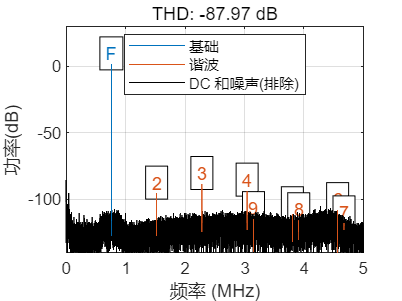

ans = -87.9689

thd(vout, Fs, 9, 'aliased')

[r,harmpow,harmfreq] = thd(vout, Fs, 9, 'aliased')

r = -87.9689

harmpow =     1.4562
  -95.6506
  -88.3728
  -93.4198
 -111.1205
 -104.7710
 -117.9738
 -115.3206
 -113.2159


harmfreq = 	1.0e+06 *

    0.7610
    1.5220
    2.2830
    3.0440
    3.8050
    4.5662
    4.6729
    3.9121
    3.1507


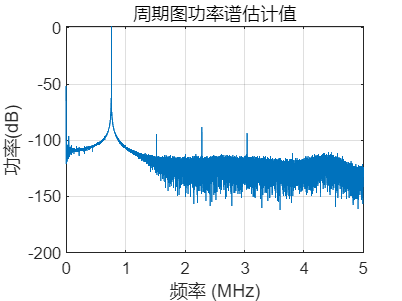

periodogram(vout, kaiser(M), M, Fs, "onesided", "power")